%Isabela Resendez A01194082
%Edge Detection
%Semana 1 Sesion 2


## Cargar Imagenes

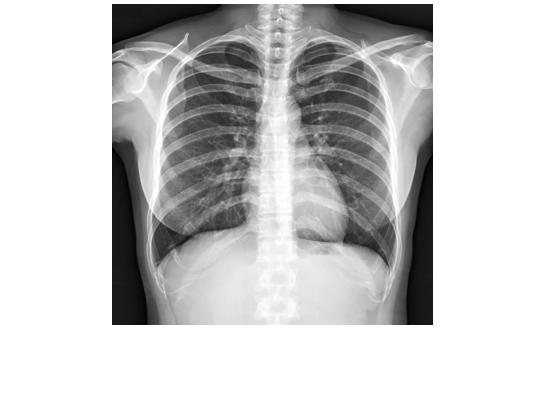

f=imread('radiograph1.jpg');
f=imresize(f,0.25);
f=double(f(:,:,1));
imshow(f,[])

## Utilizar Mascara

edgex=[1,-1] % crear mascara

edgex =      1    -1


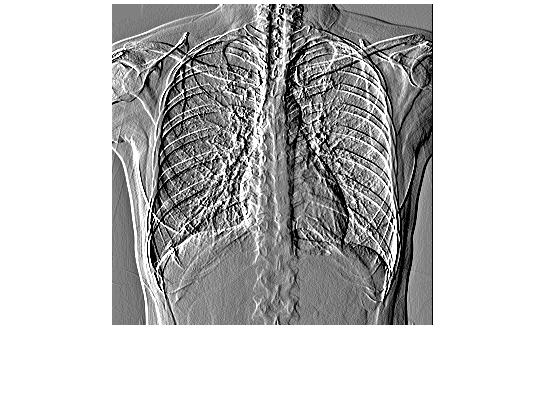

g1=conv2(f,edgex,'same'); %convolution
imshow(g1,[-10,10]); % proyectar imagen convolucion

edgey=[-1 -2 -1;0,0,0;1,2,1]/8

edgey =    -0.1250   -0.2500   -0.1250
         0         0         0
    0.1250    0.2500    0.1250


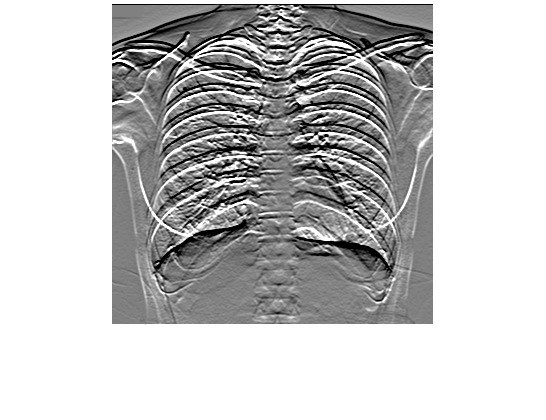

g2=conv2(f,edgey,'same');
imshow(g2,[-10,10])

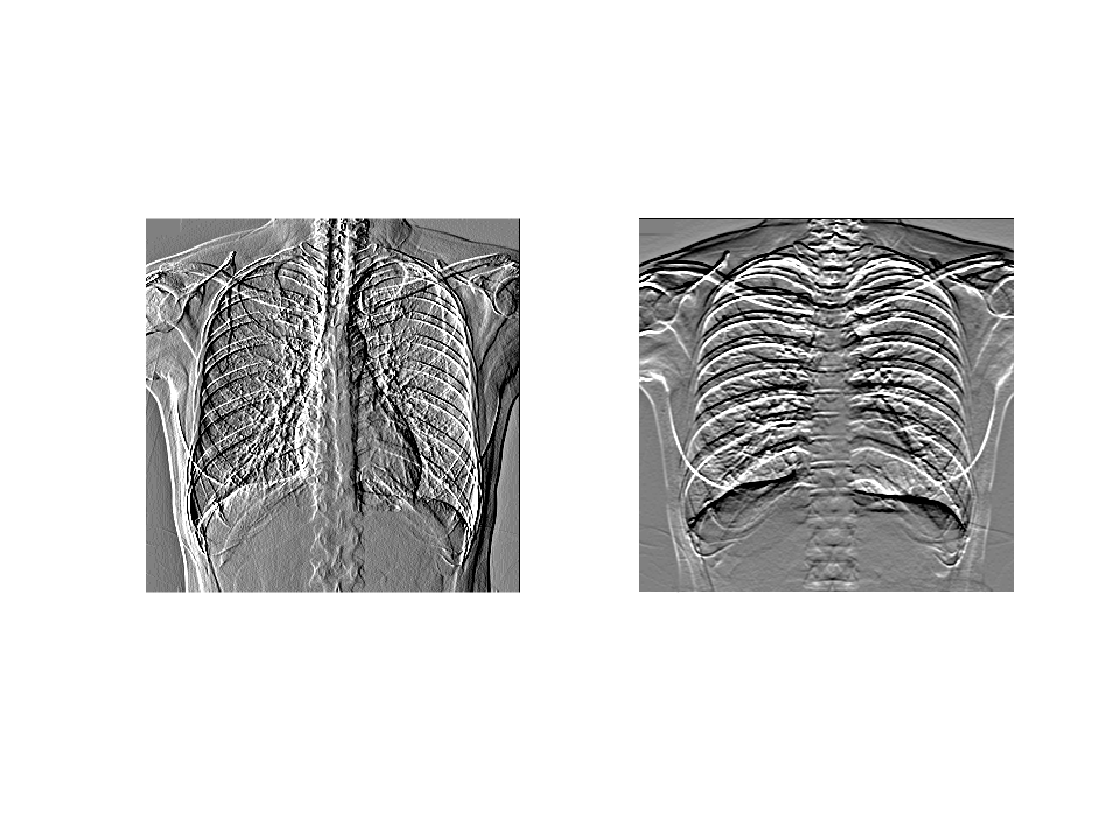

figure(2)
subplot(1,2,1)
imshow(g1,[-10,10])
subplot(1,2,2)
imshow(g2,[-10,10])

## Figure 3

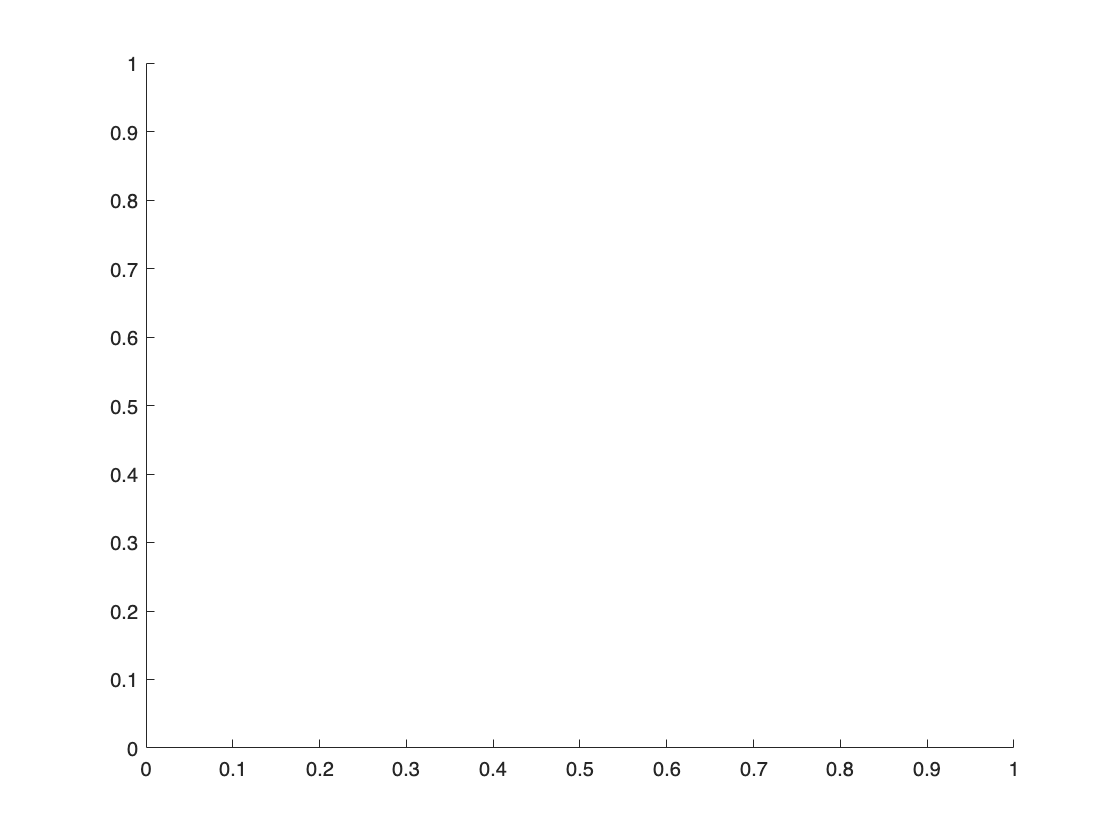

figure(3)
subplot(1,1,1)

## Sobel Mask Dx y Dy para Image Gradient

edgex=[1,0,-1;2,0,-2;1,0,-1]/8

edgex =     0.1250         0   -0.1250
    0.2500         0   -0.2500
    0.1250         0   -0.1250


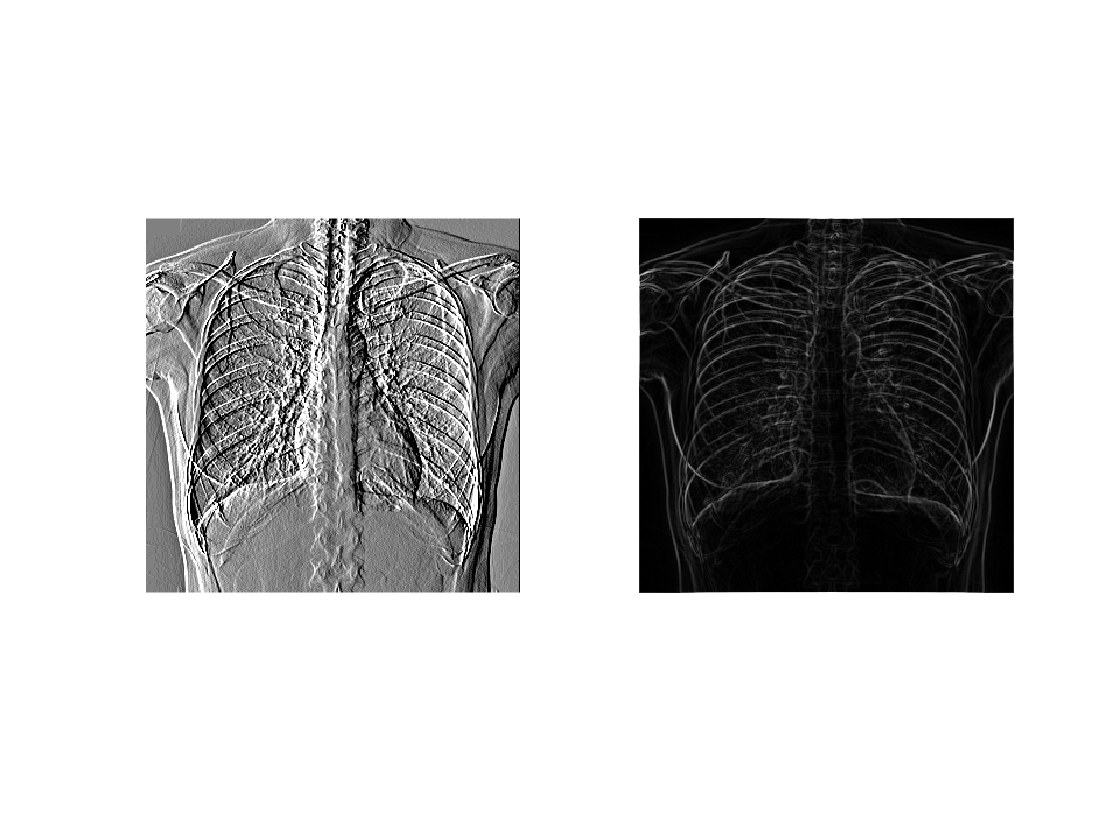

gx=conv2(f,edgex,'same');
gy=conv2(f,edgey,'same');
mag=abs(gx)+abs(gy); % magnitud gradiente
imshow(mag,[]);

## Estimar Nivel de Ruido

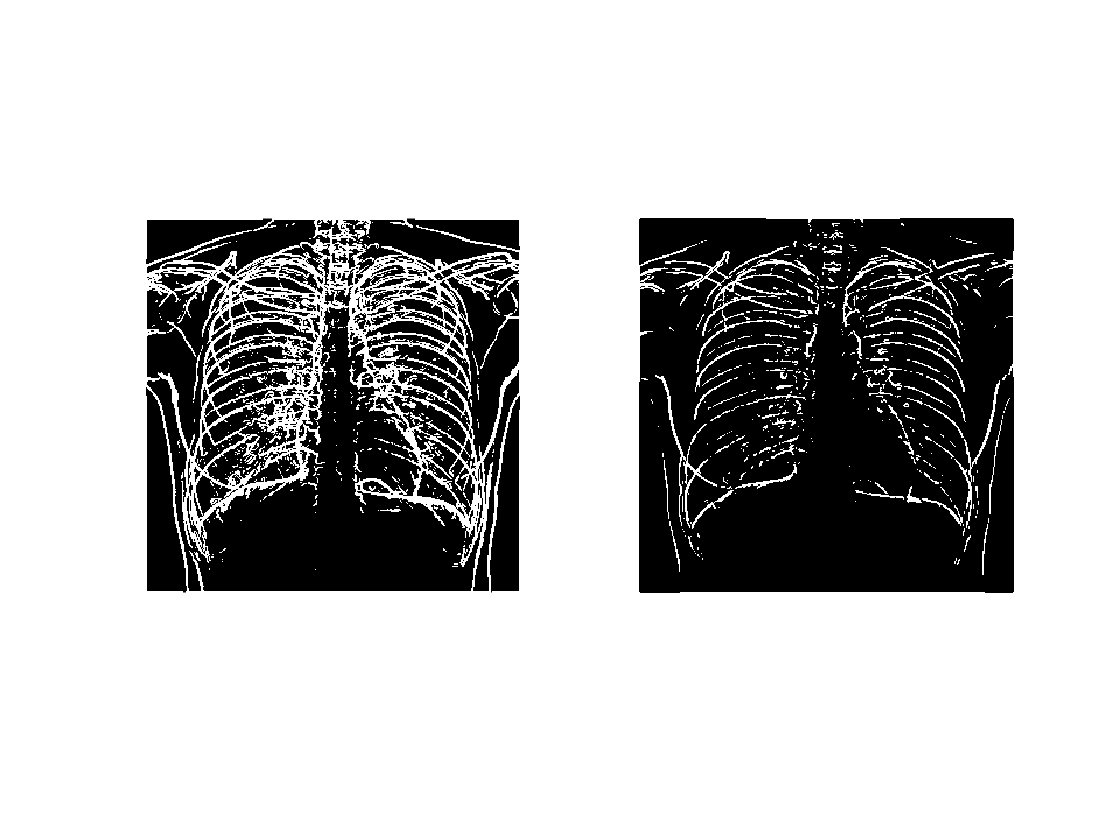

noisemask = [-1, 0 1];
noiseimage = conv2(f,noisemask,'same');
noisevariance = mean2(noiseimage.^2);
noisestd = sqrt(noisevariance/2);
edgedetection1 = mag > noisestd;
edgedetection2 = mag > 2*noisestd;
subplot(1,2,1)
imshow(edgedetection1,[]);
subplot(1,2,2)
imshow(edgedetection2,[]);

## Figure 4

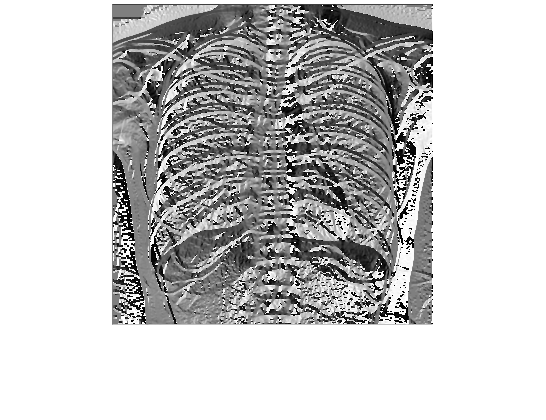

figure(4)
subplot(1,1,1)
angle=atan2(gy,gx);
imshow(angle,[]);

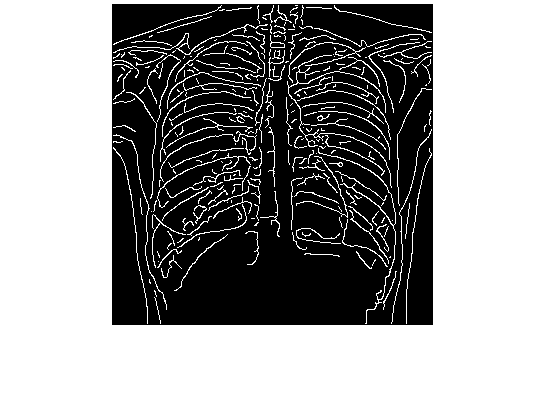

edgcany=edge(f,'Canny');
imshow(edgcany,[]);